% The following matrix implements the SIR dynamics example from Chapter 9.3
% of the textbook.
A = [0.95 0.04 0 0; 
    0.05 0.85 0 0; 
    0 0.1 1 0; 
    0 0.01 0 1];
k_infections = 0.001;
k_recover = 0.01;
k_fatality = 0.01;
ic_susc = 0.9;
ic_inf = 0.1;
ic_rec = 0;
ic_fatality = 0;
x=[k_infections,k_recover,k_fatality,ic_susc,ic_inf,ic_rec,ic_fatality];
A = [1-k_infections 0 0 0; 
    k_infections 1-k_recover-k_fatality 0 0; 
    0 k_recover 1 0; 
    0 k_fatality 0 1]

A =     0.9990         0         0         0
    0.0010    0.9800         0         0
         0    0.0100    1.0000         0
         0    0.0100         0    1.0000



% The following matrix is needed to use the lsim function to simulate the
% system in question
B = zeros(4,1);

% initial conditions (i.e., values of S, I, R, D at t=0).
x0 = [0.9 0.1 0 0];

% Here is a compact way to simulate a linear dynamical system.
% Type 'help ss', 'help lsim', etc., to learn about how these functions work!!
sys_sir_base = ss(A,B,eye(4),zeros(4,1),1);
Y = lsim(sys_sir_base,zeros(500,1),linspace(0,499,500),x0);

sirafun= @(x)siroutput(x,t,Y);
% X = [k_inf k_fat k_rec S I R D]
cost = norm(Y(:,2)-coviddata(1:500,1))+norm(Y(:,4)-coviddata(1:500,2))

cost = 4.5085

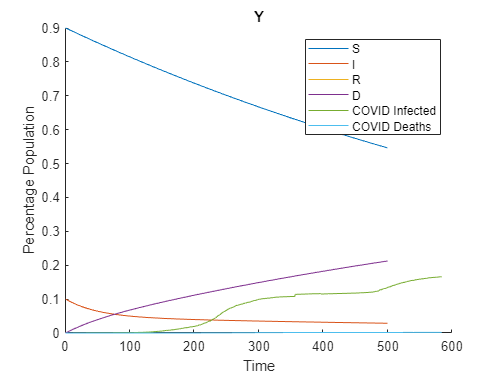


% plot the output trajectory
figure;
hold on
plot(Y);
plot(coviddata);
legend('S','I','R','D','COVID Infected','COVID Deaths');
title("Y");
xlabel('Time')
ylabel('Percentage Population');


% x = zeros(4, 1000);
% x(:,1) = [1; 0; 0; 0];
% for i=2:1000
%     x(:,i) = A*x(:,i-1);
% end
% x = x';
% figure;
% plot(x);
% legend('S','I','R','D');
% title("X");
% xlabel('Time')
% ylabel('Percentage Population');